## **Import Data**

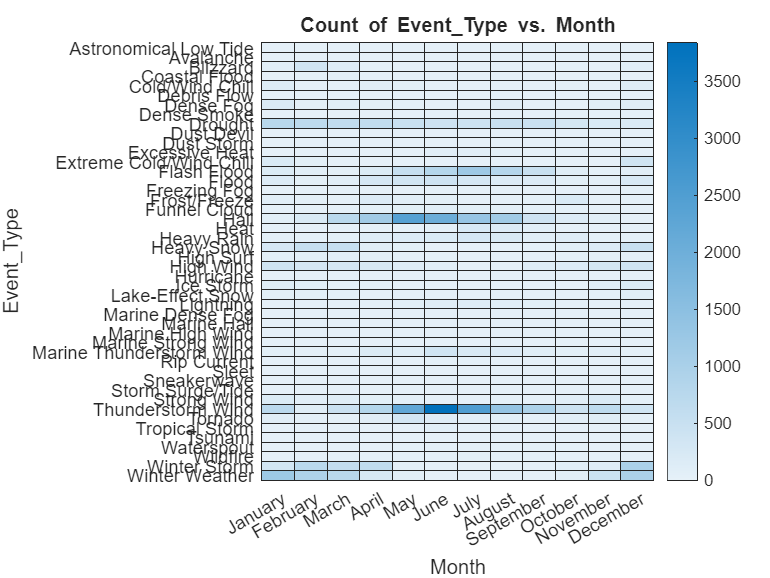

events=importStormData("StormEvents_2013.csv");
monthOrder = ["January", "February", "March", "April", "May", "June", "July",...
    "August", "September", "October", "November", "December"];
events.Month=reordercats(events.Month,monthOrder);
heatmap(events,"Month","Event_Type")

new

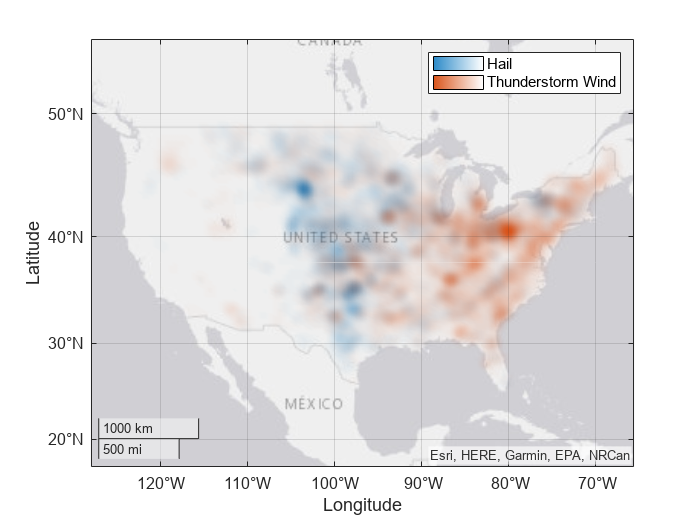

Hind=events(events.Event_Type=="Hail",:);
geodensityplot(Hind.Begin_Lat,Hind.Begin_Lon);
geolimits([17.0 55.2],[-128.0 -65.6]);
hold on
Twind=events(events.Event_Type=="Thunderstorm Wind",:);
geodensityplot(Twind.Begin_Lat,Twind.Begin_Lon);
hold off
legend("Hail","Thunderstorm Wind");

Lat= ;%Choosing by edit field and then type of data double and execution nothing 
Lon= ;